**Multiobjective Optimization**

Consider the linear multiobjective problem:


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & \left(x_1 +2x_2 -3x_3 \right),\left({-x}_1 -x_2 -x_3 \right),\left(-4x_1 -2x_2 +x_3 \right)\\
\mathrm{subject}\;\mathrm{to} & x_1 +x_2 +x_3 \le 10\\
\; & x_3 \le 5\\
\; & -x_1 \le 0\\
\; & -x_2 \le 0\\
\; & -x_3 \le 0
\end{array}\right.$$
 

Check if the points u = (5, 0, 5), v = (4, 4, 2) and w = (1, 4, 4) are minima or weak minima by solving the corresponding auxiliary problems.

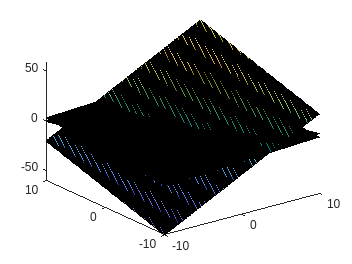

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

x1 = -10:0.1:10;
x2 = -10:0.1:10;

[X1,X2] = meshgrid(x1,x2);

X3 = (X1+2.*X2)/3;
X4 = (-X1-X2);
X5 = (4.*X1+2.*X2);
surface(X1,X2,X3, 'FaceAlpha',0.5);
hold on
surface(X1,X2,X4,'FaceAlpha',0.2);
surface(X1,X2,X5, 'FaceAlpha',0.7);
view(3);
hold off

% Environment Variables
C = [ 1  2 -3
     -1 -1 -1
     -4 -2  1];

A = [ 1  1  1
      0  0  1
     -1  0  0
      0 -1  0
      0  0 -1];

b = [10
      5
      0
      0
      0];

u = [5
     0
     5];

v = [4
     4
     2];

w = [1
     4
     4];

y = v;

% Variables number
n = size(C,2);
% Functions number
p = size(C,1);
% Constraints number
m = size(A,1);

% Calculate the linear Problem

c = [zeros(n,1)
    -ones(p,1)];

P = [C           eye(p)
     A           zeros(m,n)
     zeros(p,n) -eye(p)];

q = [C*y
     b
     zeros(p,1)];

% Solve the Linear Programming check minimum
options = optimset('Display', 'off');
[~, minimum] = linprog(c,P,q, [],[],[],[],options)

minimum = -13.0000


% Solve the Linear Programming check weak minimum

c = [zeros(n,1)
     zeros(p,1)
     -1];

P = [zeros(p,n)  -eye(p)    ones(p,1)
     C           eye(p)     zeros(p,1)
     A           zeros(m,n) zeros(m,1)
     zeros(p,n) -eye(p)     zeros(p,1)];

q = [zeros(p,1)
     C*y
     b
     zeros(p,1)];


[~, minimum_weak] = linprog(c,P,q, [],[],[],[],options)

minimum_weak = 0